## project2.mlx, Leo Berman & Justin Ok, 10/5/2023

# Signals Project 2

Leo Berman & Justin Ok

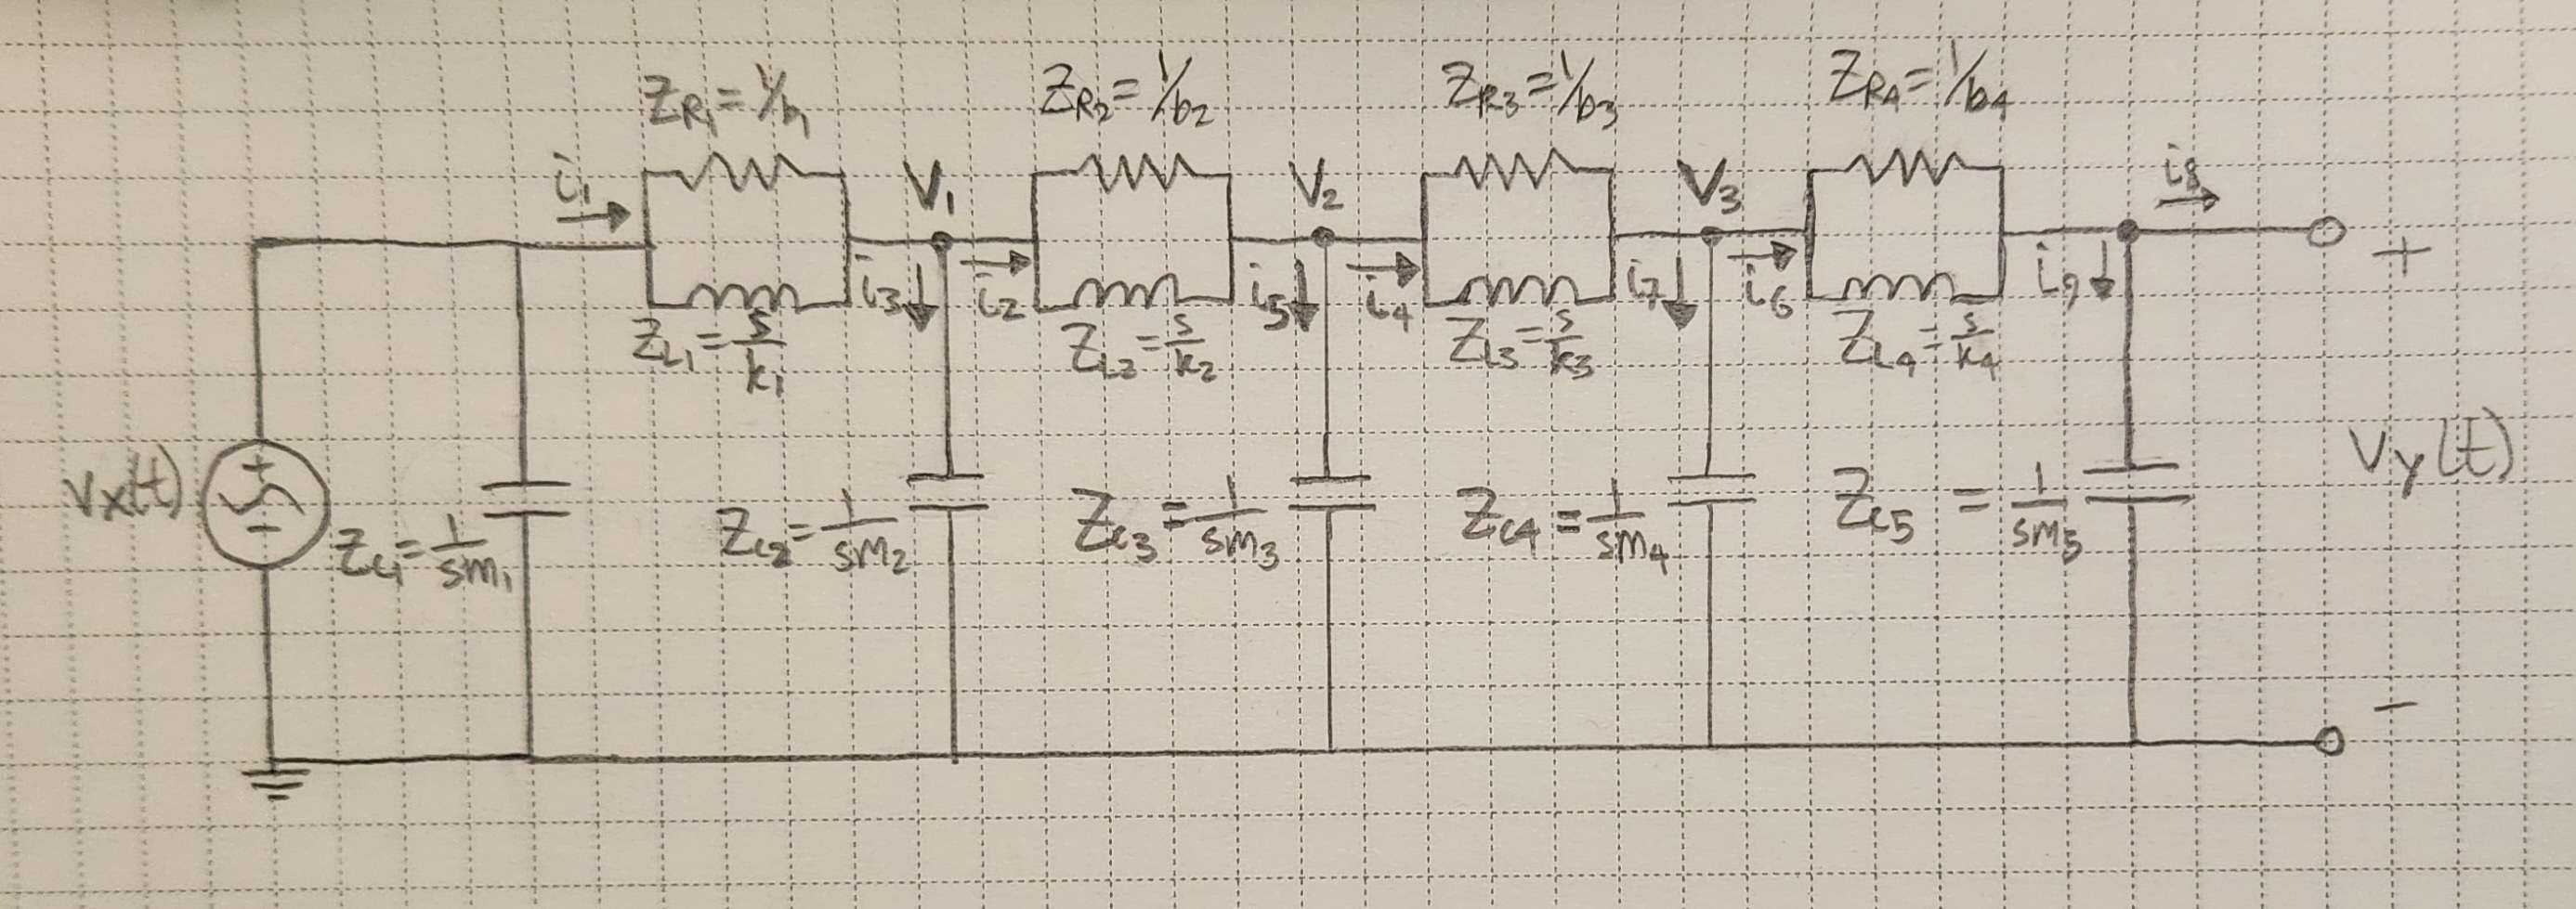    

## Symming s, t, setting input as impulse to find transfer function

clear all
close all
clc
syms s t

## Physical properties of the human/chair combo

b = 90;
k = 3500;
m1 = 30; % chair weight kg
k1 = 2139; % spring constant of chair
m2 = 8.164; % lower torso kg
k2 = k; % spring constant of bones
b2 = b; % damping constant of soft tissue
m3 = 11.953; % middle torso kg
k3 = k; % spring constant of bones
b3 = b; % damping constant of soft tissue
m4 = 11.654; % upper torso kg
k4 = k; % spring constant of bones
b4 = b; % damping constant of soft tissue
m5 = 5.018; % head weight kg
b1 = sqrt(k1*(m1+m2+m3+m4+m5)) % damping constant of chair

b1 = 377.9705

## Circuit conversion into s domain

ZC1 = 1/(s*m1);
ZL1 = s/k1;
ZR1 = 1/b1;
ZC2 = 1/(s*m2);
ZL2 = s/k2;
ZR2 = 1/b2;
ZC3 = 1/(s*m3);
ZL3 = s/k3;
ZR3 = 1/b3;
ZC4 = 1/(s*m4);
ZL4 = s/k4;
ZR4 = 1/b4;
ZC5 = 1/(s*m5);
ZRL1 = (1/ZR1 + 1/ZL1)^-1;
ZRL2 = (1/ZR2 + 1/ZL2)^-1;
ZRL3 = (1/ZR3 + 1/ZL3)^-1;
ZRL4 = (1/ZR4 + 1/ZL4)^-1;

## Nodal

% Simulating Variables
syms I1 I2 I3 I4 I5 I6 I7 I8 I9

% Nodal Equations
eq1 = I1 == I2 + I3;
eq2 = I2 == I4 + I5;
eq3 = I4 == I6 + I7;
eq4 = I6 == I8 + I9;

% Defining our impulse
vx = dirac(t);
Vx = laplace(vx);
syms V1 V2 V3 VY

% Defining Current's
eq5 = I1 == (Vx-V1)/ZRL1;
eq6 = I2 == (V1-V2)/ZRL2;
eq7 = I3 == V1/ZC2;
eq8 = I4 == (V2-V3)/ZRL3;
eq9 = I5 == V2/ZC3;
eq10 = I6 == (V3-VY)/ZRL4;
eq11 = I7 == V3/ZC4;
eq12 = I8 == 0;
eq13 = I9 == VY/ZC5;

% Getting solution Matrixes
eqns = [eq1 eq2 eq3 eq4 eq5 eq6 eq7 eq8 eq9 eq10 eq11 eq12 eq13];
vars = [I1 I2 I3 I4 I5 I6 I7 I8 I9 V1 V2 V3 VY];

% Solving the system of equations
sol = solve(eqns,vars);

% Setting Transfer Functions For head and parts of the torso
Hs_head = partfrac(sol.VY);
% save head.mat Hs_head -mat
Hs_hightorso = partfrac(sol.V3);
Hs_lowtorso = partfrac(sol.V2);

## Getting the resonant frequency of our system

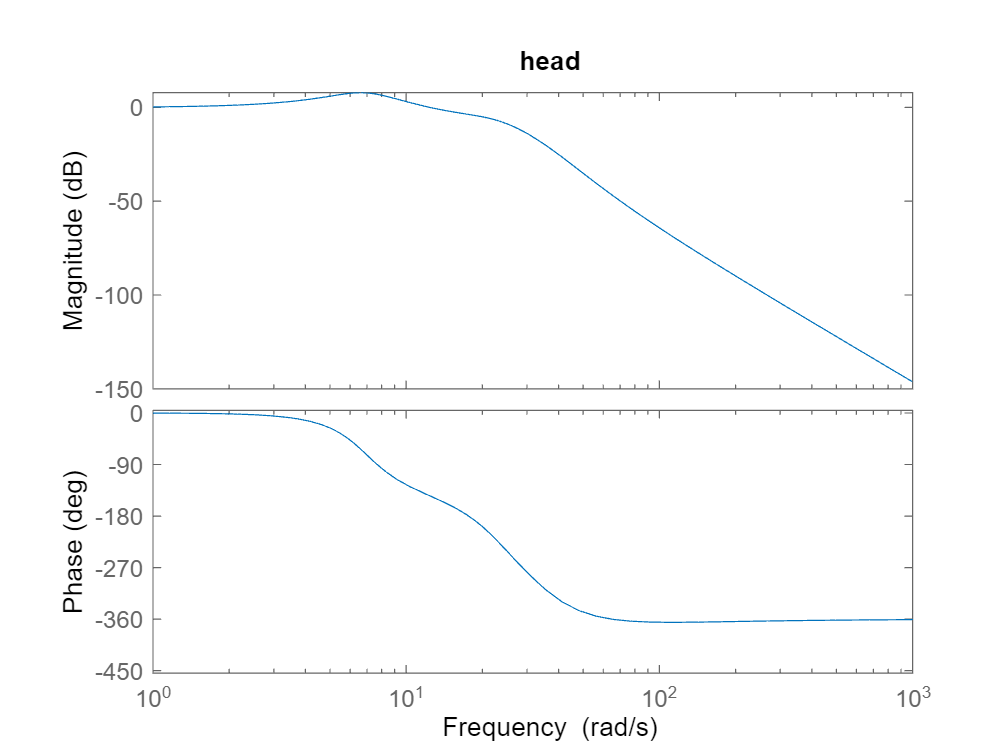

HeadGain = 0.5979

% Plotting the frequencies in order to determine where we are amplifying
% frequencies to make sure we aren't distrubing any organs
HeadGain = getfreqresp(Hs_head,'head',[19 21])

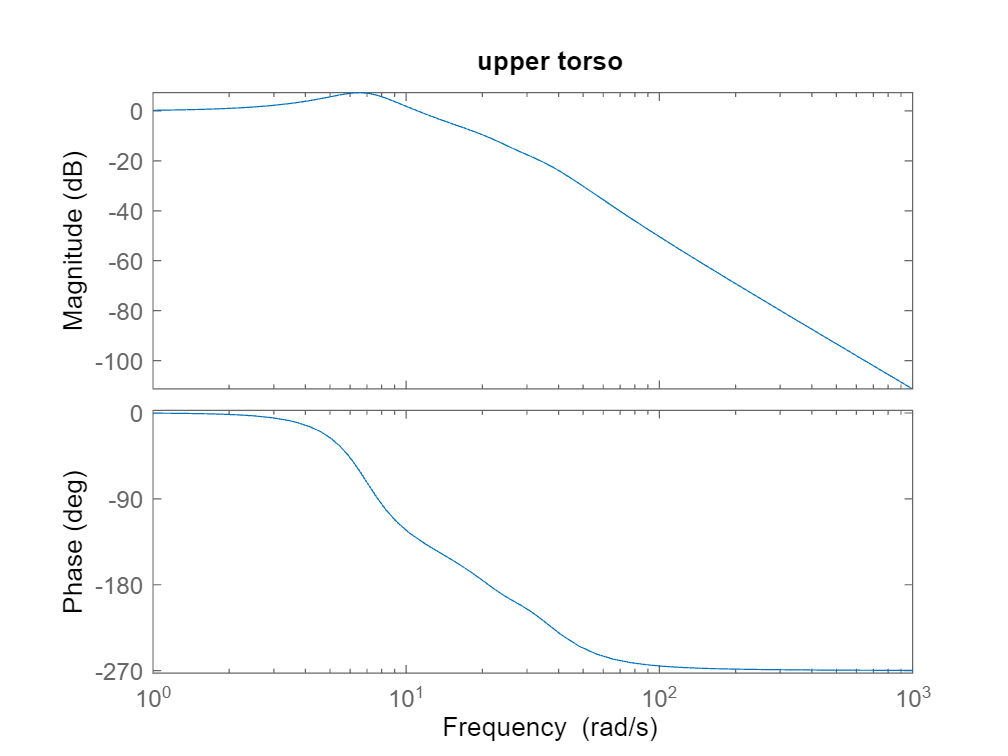

UpperTorsoGain = 2.2546

UpperTorsoGain = getfreqresp(Hs_hightorso,'upper torso',[6 8])

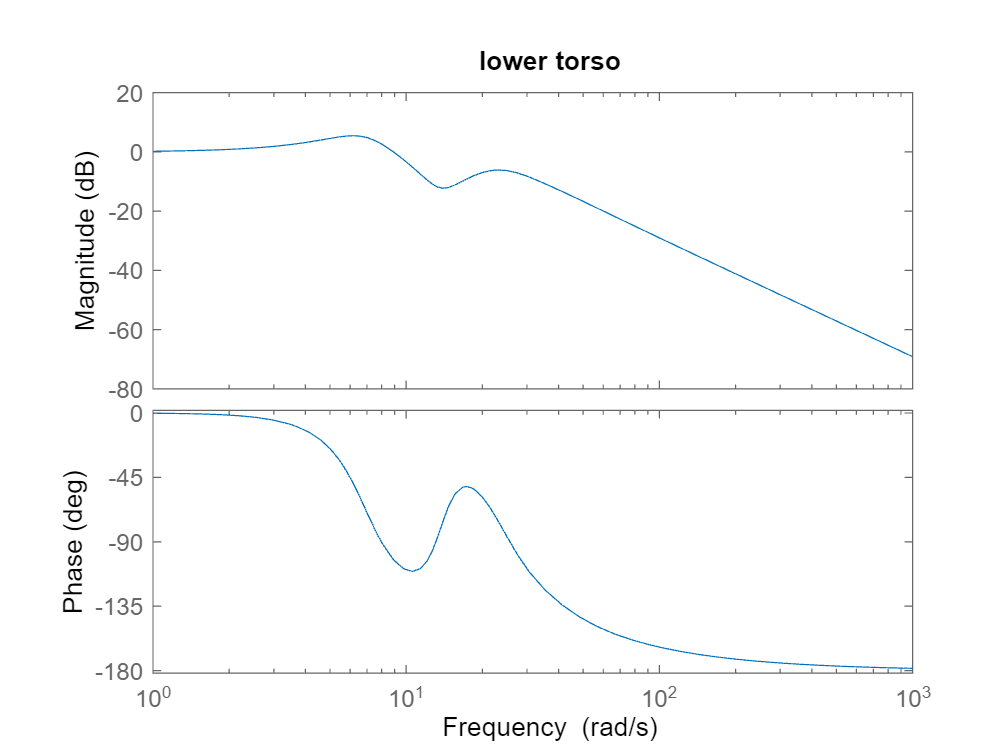

LowTorsoGain = 1.0255

LowTorsoGain = getfreqresp(Hs_lowtorso,'lower torso',[0 1])

## Response to going up and down a 6 inch high and 6 inch long curb 

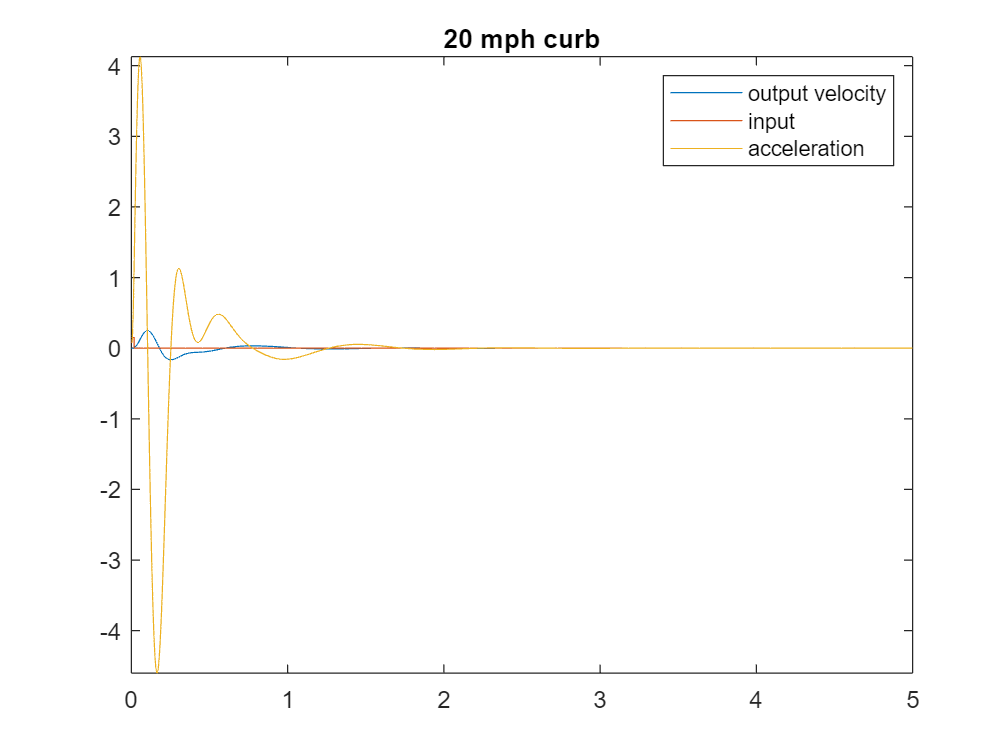

curbmax20 = 4.4180

% 20 mph
curbmax20 = findmaxaccel(Hs_head,.1524*(heaviside(t)-heaviside(t-findtime(20,6))),'20 mph curb')

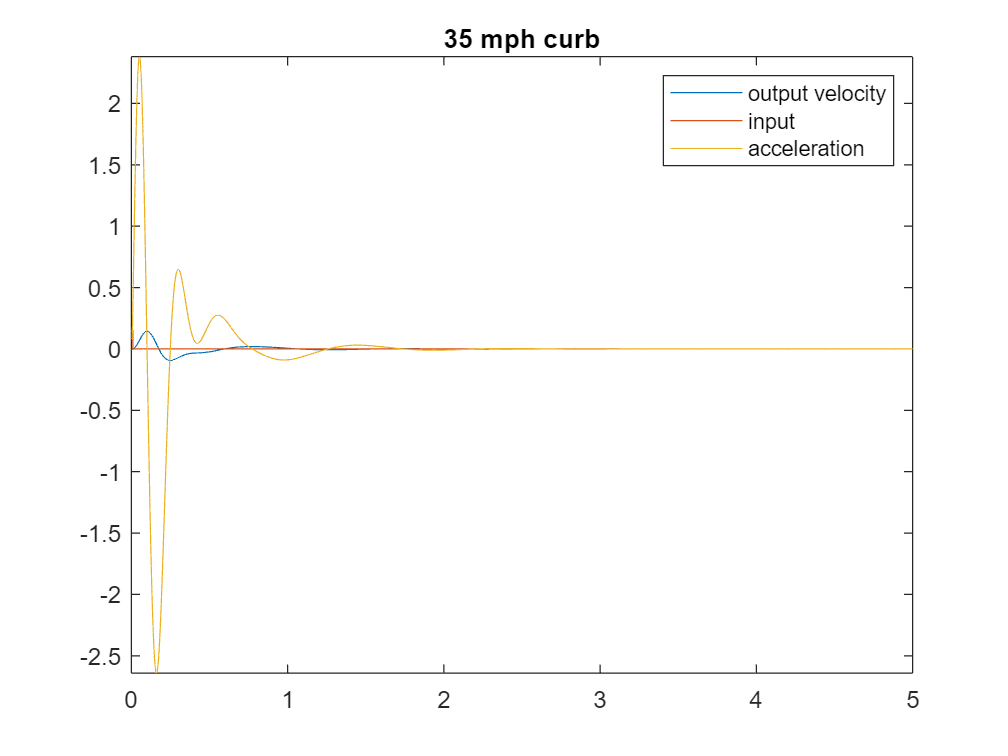

curbmax35 = 2.5930

% 35 mph
curbmax35 = findmaxaccel(Hs_head,.1524*(heaviside(t)-heaviside(t-findtime(35,6))),'35 mph curb')

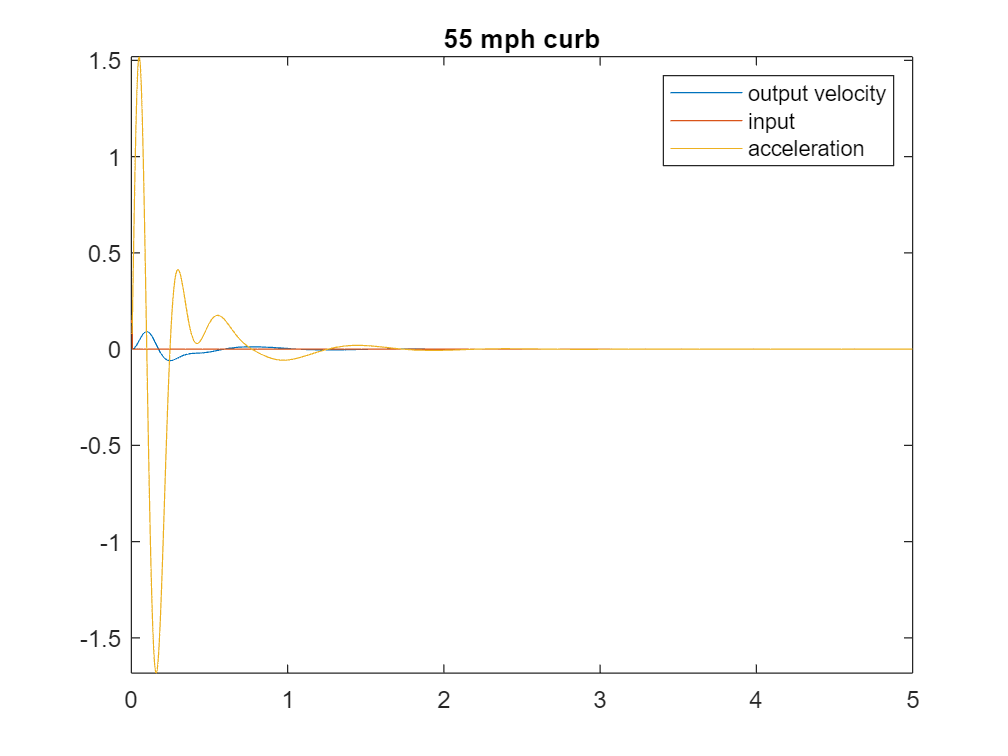

curbmax55 = 1.6646

% 55 mph
curbmax55 = findmaxaccel(Hs_head,.1524*(heaviside(t)-heaviside(t-findtime(55,6))),'55 mph curb')

## Response to going over a 3.5 inch speedbump that 54 inches long

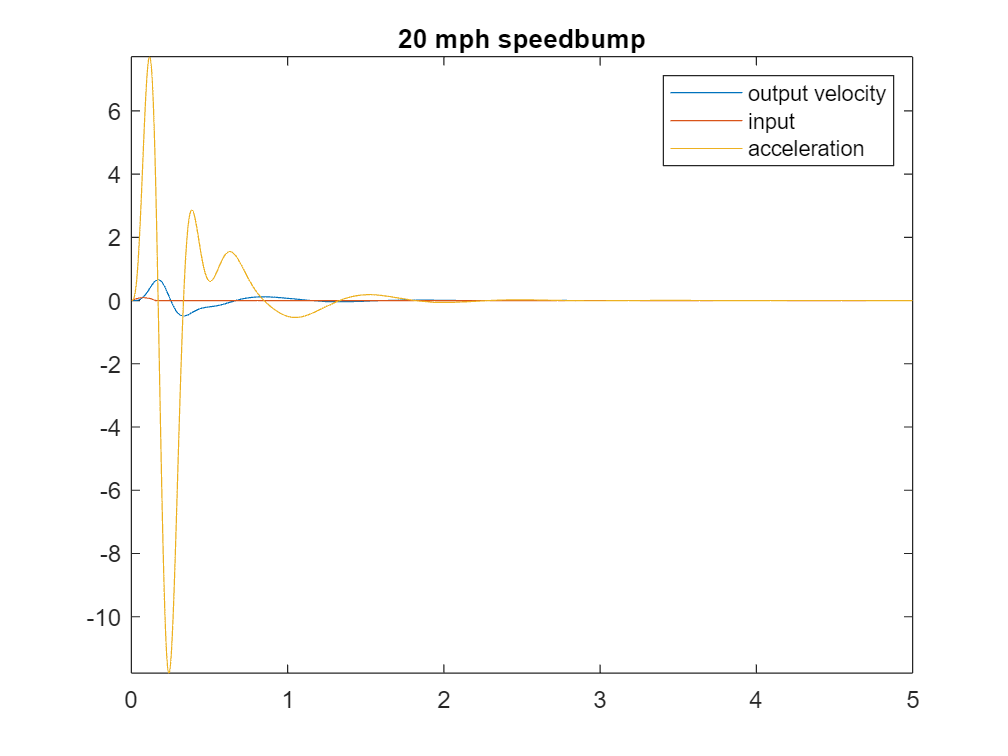

bumpmax20 = 11.7549

% 20 mph
bumpmax20 = findmaxaccel(Hs_head,(findbump(20,54,3.5))*(heaviside(t)-heaviside(t-findtime(20,54))),'20 mph speedbump')

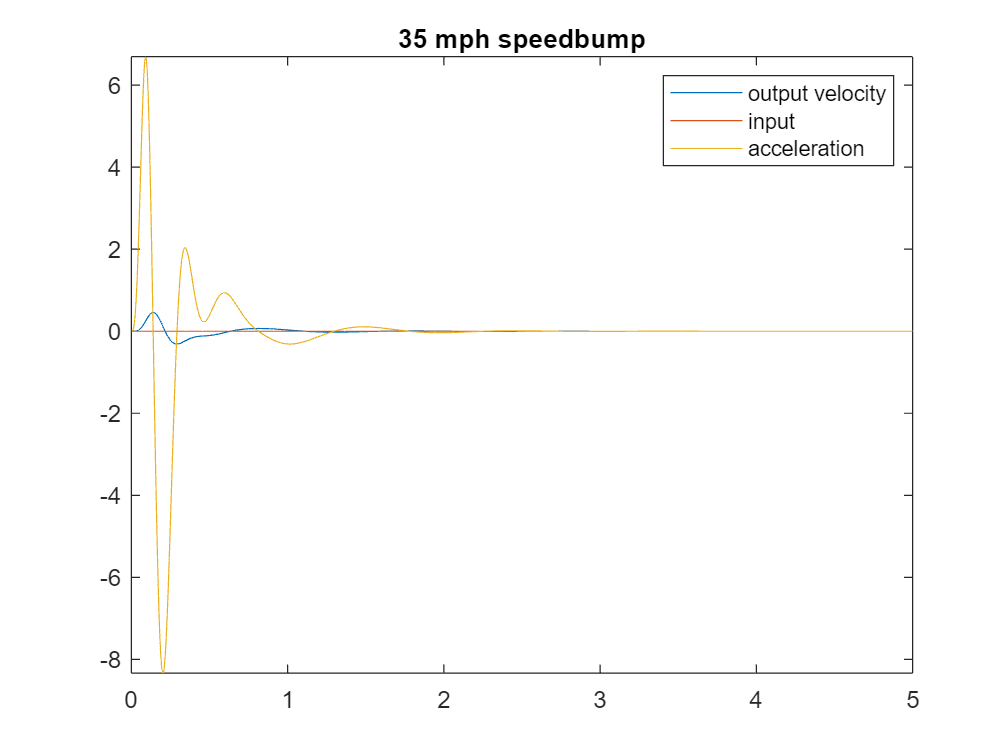

bumpmax35 = 8.0764

% 35 mph
bumpmax35 = findmaxaccel(Hs_head,(findbump(35,54,3.5))*(heaviside(t)-heaviside(t-findtime(35,54))),'35 mph speedbump')

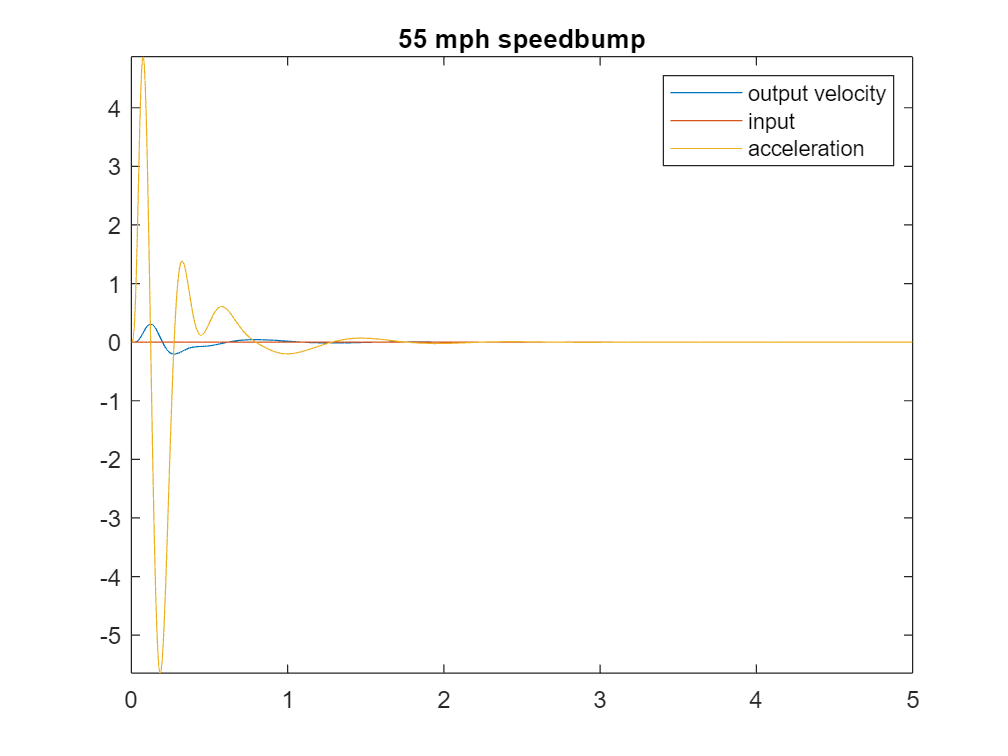

bumpmax55 = 5.6443

% 55 mph
bumpmax55 = findmaxaccel(Hs_head,(findbump(55,54,3.5))*(heaviside(t)-heaviside(t-findtime(55,54))),'55 mph speedbump')

## Response To Going Over A Curvy Pavement With 3 Cm Amplitude

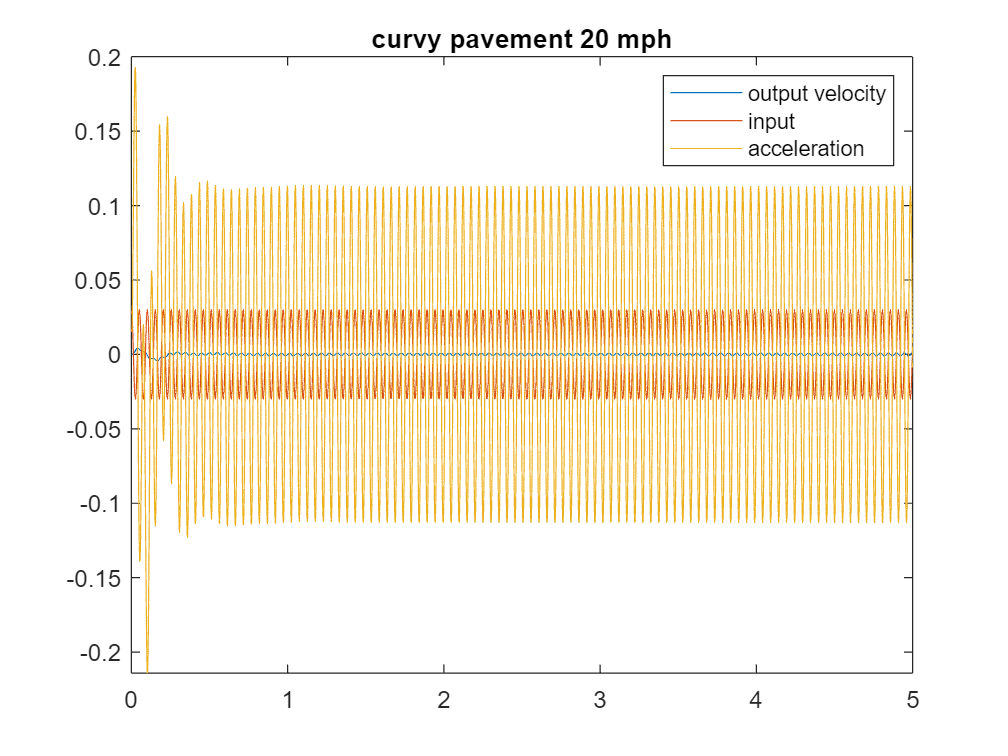

curvemax20 = 0.1522

% 20 mph
curvemax20 = findmaxaccel(Hs_head,findpave(20,18)*heaviside(t),'curvy pavement 20 mph')

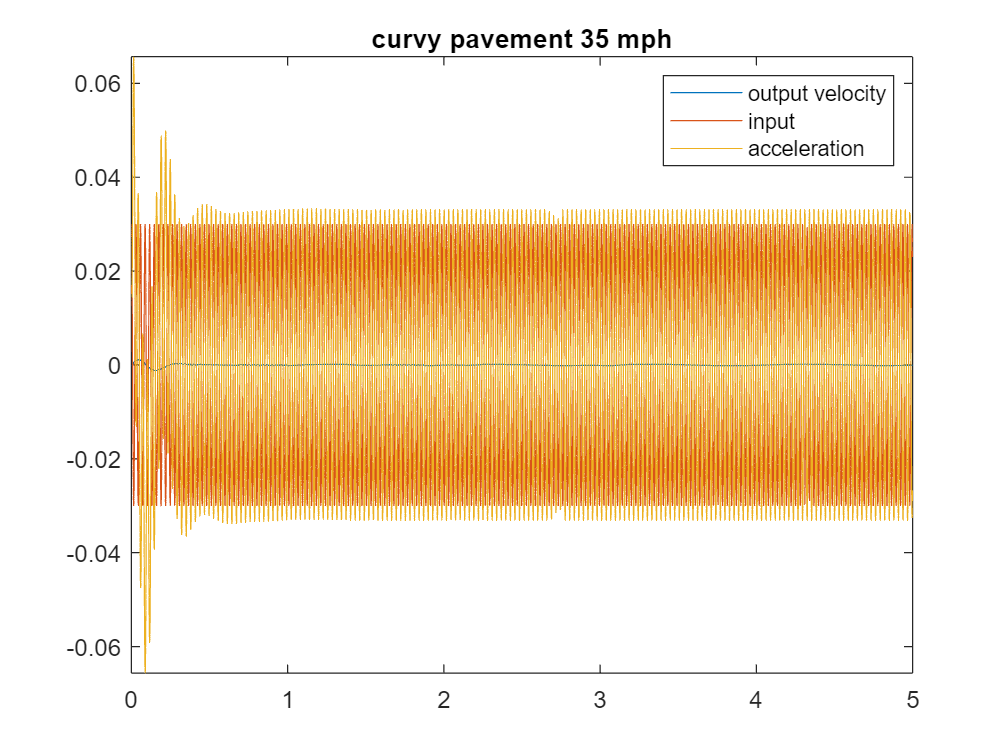

curvemax35 = 0.0552

% 35 mph
curvemax35 = findmaxaccel(Hs_head,findpave(35,18)*heaviside(t),'curvy pavement 35 mph')

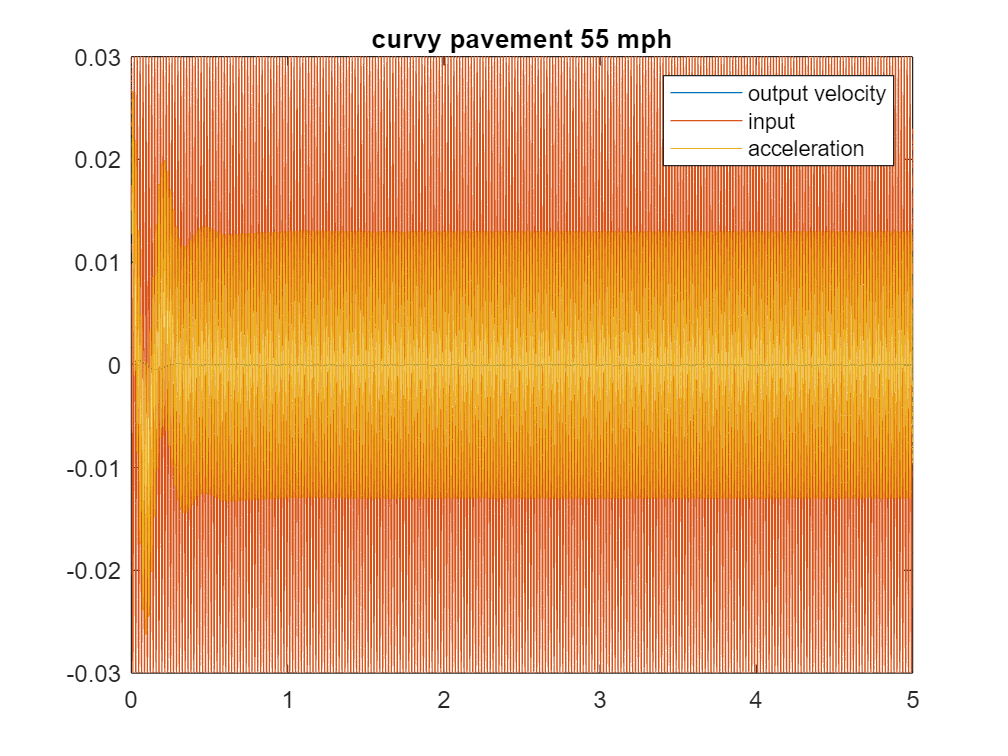

curvemax55 = 0.0251

% 55 mph
curvemax55 = findmaxaccel(Hs_head,findpave(55,18)*heaviside(t),'curvy pavement 55 mph')

## Response To Going Up A 6 Inch Curb

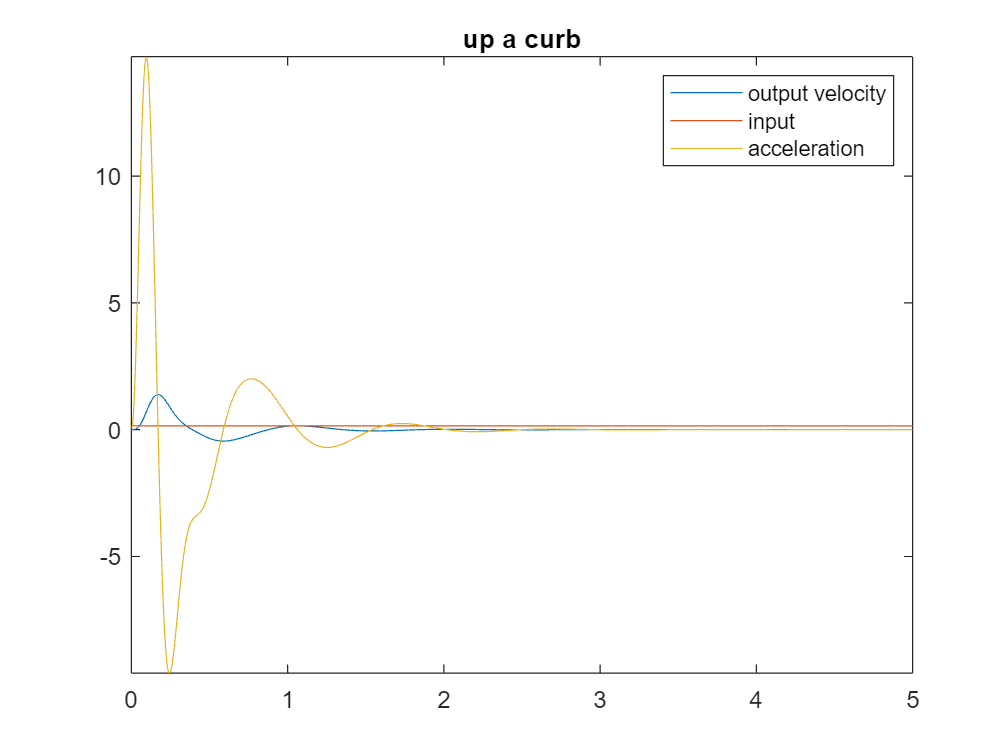

upacurbmax = 14.6639

upacurbmax = findmaxaccel(Hs_head,.1524*heaviside(t),'up a curb')

## Response To Dropping Off A 6 Inch Curb

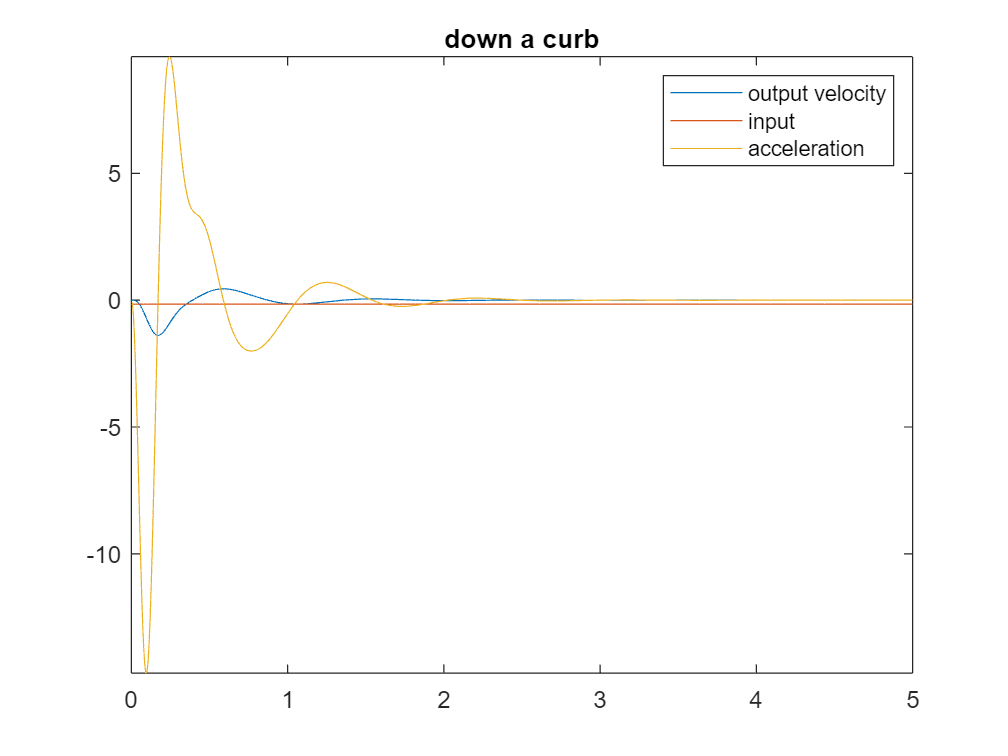

downacurbmax = 14.6639

downacurbmax = findmaxaccel(Hs_head,-.1524*heaviside(t),'down a curb')

## Response To Pothole

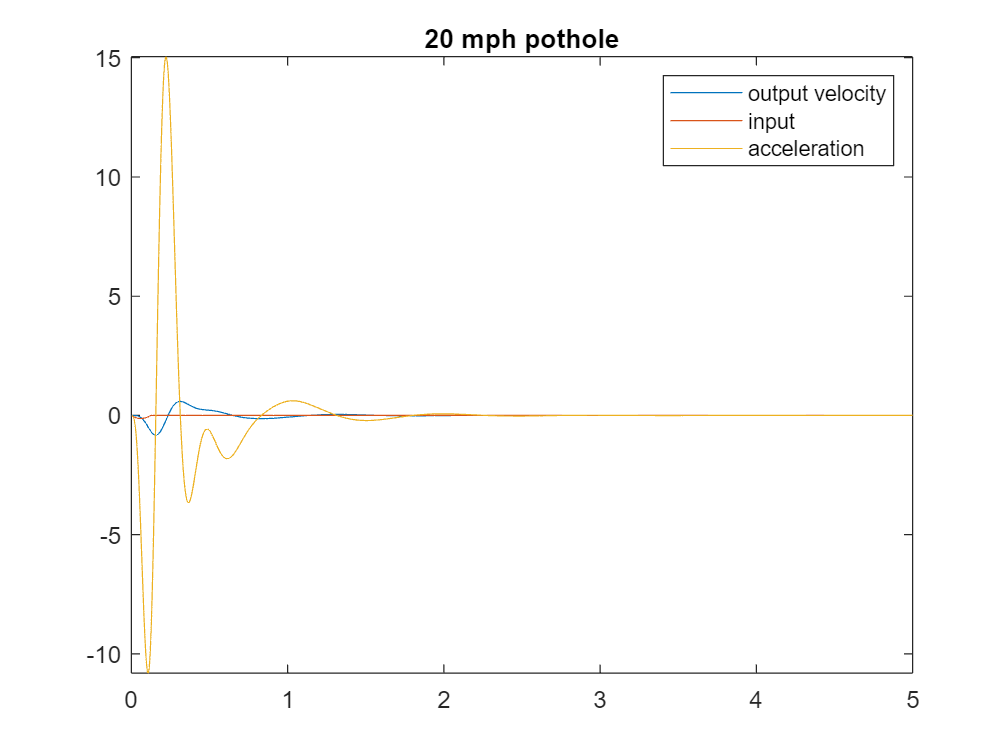

potholemax20 = 14.7668

% 20 mph
potholemax20 = findmaxaccel(Hs_head,-(findbump(20,43,5))*(heaviside(t)-heaviside(t-findtime(20,43))),'20 mph pothole')

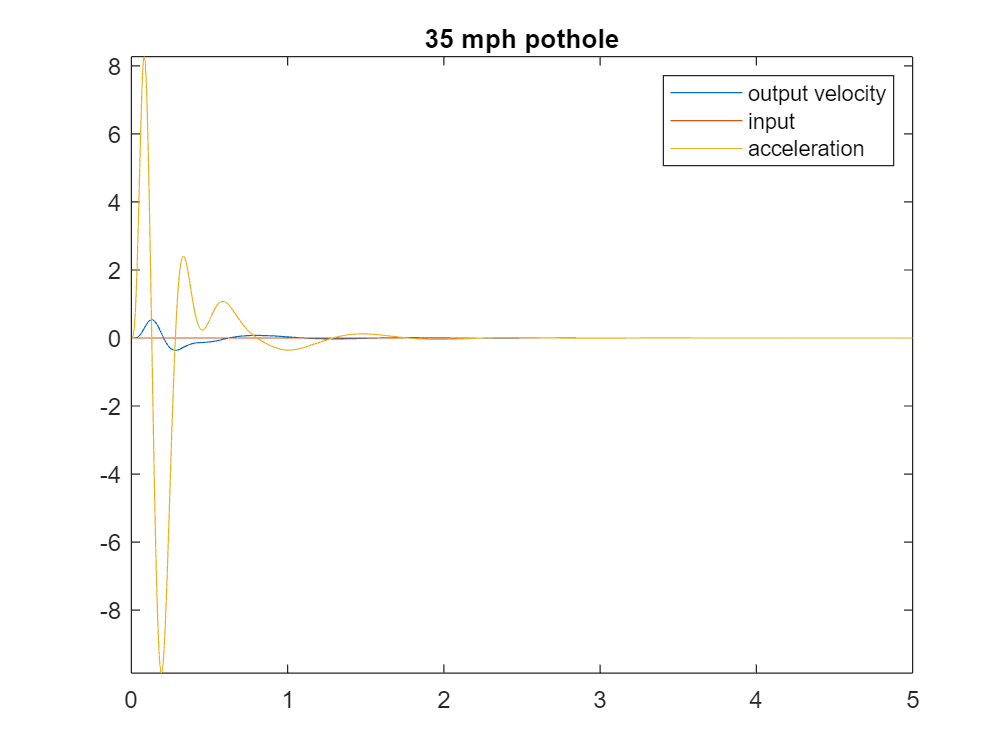

potholemax35 = 9.6209

% 35 mph
potholemax35 = findmaxaccel(Hs_head,(findbump(35,43,5))*(heaviside(t)-heaviside(t-findtime(35,43))),'35 mph pothole')

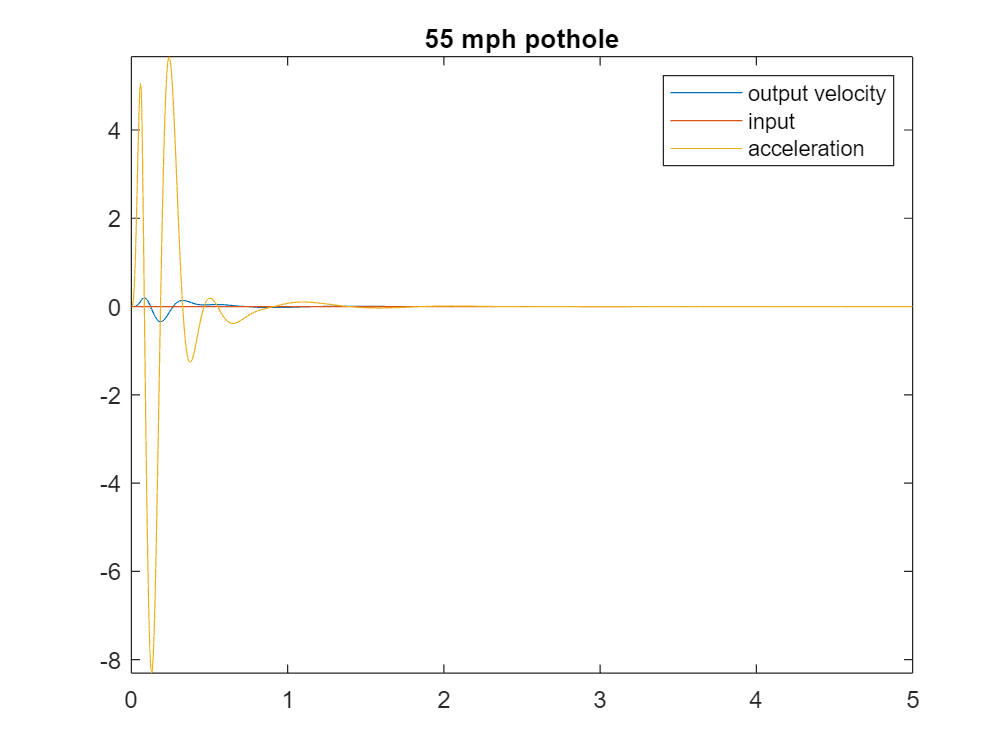

potholemax55 = 8.0754

% 55 mph
potholemax55 = findmaxaccel(Hs_head,(findbump(55,43,5))*(heaviside(t)-heaviside(t-findtime(35,43))),'55 mph pothole')

## Maximum Head Acceleration

totalmax = max([potholemax55,potholemax35,potholemax20,downacurbmax,upacurbmax,curvemax55,curvemax35,curvemax20,bumpmax55,bumpmax35,bumpmax20,curbmax55,curbmax35,curbmax20])

totalmax = 14.7668